========== START iteration: 1 ==========


Generate number of outliers:
     9



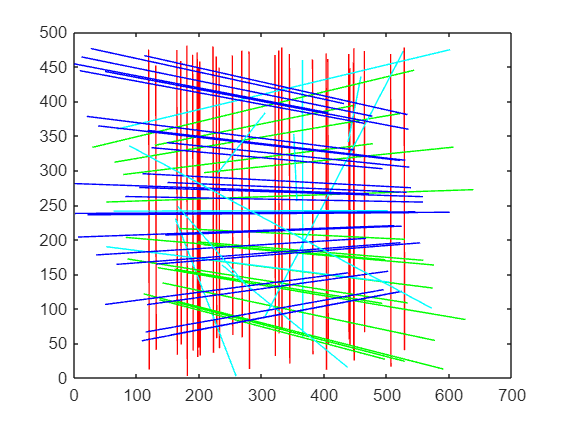

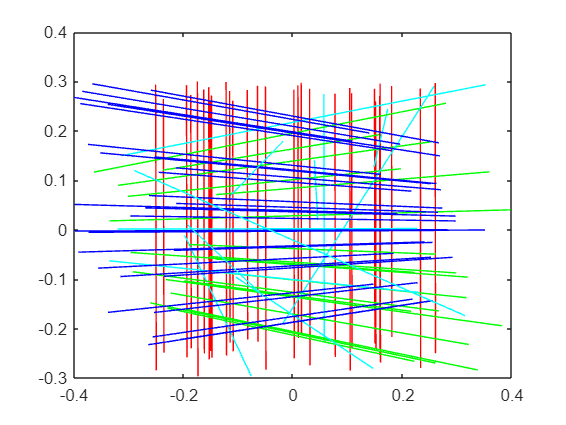

Ground truth Manhattan frame


MF_GT =   -0.001551240662876   0.668199887621236  -0.743980177044639
   0.999996578786644  -0.000530435087507  -0.002561455372620
  -0.002106197382445  -0.743981605163451  -0.668196778734379


Execution of script clean as a function is not supported:
D:\OneDrive\OneDrive - The Chinese University of Hong Kong\Desktop\YALMIP-master\extras\@ndsdpvar\clean.m

Error in ndsdpvar (line 59)
X = clean(X);

Error in sdpvar (line 150)
        sys = ndsdpvar(vara

clear all;
close all;
clc;


rng(42, 'twister');

addpath(genpath("D:\OneDrive\OneDrive - The Chinese University of Hong Kong\Desktop\YALMIP-master"))
addpath(genpath("C:\Program Files\Mosek\10.1\toolbox\r2017a"))
cd ../../MATLAB/
addpath(genpath(pwd));
cd main

%% -------------- Parameter settings --------------
param.vanishing_point_num = 3;
param.line_num = 90;
param.rand_data_gen = true;
param.noise = 0.1;
param.c = 0.03;
param.max_line_processing = 8;
param.fast_solver = true;
param.eigen_thredhold = 9;
param.recover_thredhold = 0.01;

iter_param.iteration = 1000;
iter_param.outlier_ratio = 0.1:0.1:0.7;

results_template = zeros(iter_param.iteration);
results_cell_template.time = results_template;
results_cell_template.error_vp = results_template;
results_cell_template.error_3d = results_template;
results_cell_template.optimal = results_template;
results_cell_template.accuracy = results_template;
results_cell_template.precision = results_template;
results_cell_template.recall = results_template;
results_cell_template.f1_score = results_template;
results_cell_template.gt_vp = cell(iter_param.iteration);
results_cell_template.est_vp = cell(iter_param.iteration);
results_cell_template.gt_correspond = cell(iter_param.iteration);
results_cell_template.est_correspond = cell(iter_param.iteration);
results_cell_template.parallel_line = cell(iter_param.iteration);

line_distribution_results = cell(size(iter_param.outlier_ratio, 2));
for idx = 1:iter_param.iteration
    results{idx} = results_cell_template;
end


for outlier_idx = 1:size(iter_param.outlier_ratio, 2)
    outlier_ratio = iter_param.outlier_ratio(outlier_idx);

    for iteration_i = 1:iter_param.iteration
        fprintf('========== START iteration: %d ==========\n', iteration_i);
        
        line1_num = randi([30,50]);
        line2_num = randi([20,40]);
        line3_num = param.line_num - line1_num - line2_num;
        param.line_inlier_num = param.line_num;
        while line3_num - (param.line_inlier_num/3) < 2
            line1_num = randi([30,50]);
            line2_num = randi([20,40]);
            line3_num = param.line_num - line1_num - line2_num;
        end
        param.line_seg = [line1_num, line2_num, line3_num];
        inlier1_num = line1_num - param.line_inlier_num/3;
        inlier2_num = line2_num - param.line_inlier_num/3;
        inlier3_num = line3_num - param.line_inlier_num/3;
        param.line_inlier_seg = [inlier1_num, inlier2_num, inlier3_num];

        [gt_correspond_list, all_2D_lines_norm, uncertainty, parallel_line_list, MF_GT, K] = ...
            Synthetic_GenerateData(outlier_ratio, param);

        gt_vp_list = MF_GT';
        disp('Ground truth Manhattan frame')
        MF_GT
        tic
        [optimal_solution, est_vp_list, est_correspond_list, total_iter] =...
                                IRCRLS_VP(parallel_line_list, all_2D_lines_norm, param, uncertainty);
        time = toc;

        disp('Estimated Manhattan frame')
        est_vp_list'
        
        [error_vp,error_3d,accuracy,precision,recall,f1_score] = get_results(gt_vp_list, gt_correspond_list, est_vp_list, est_correspond_list);
        fprintf('Time: %f, accuracy: %f, precision: %f, recall: %f, f1_score: %f, error_vp: %f, error_3d: %f **********\n',...
            time, accuracy, precision, recall, f1_score, error_vp, error_3d);

        error_angular_diff = compute_vanishing_point_error(est_vp_list', gt_vp_list');
        error_angular_diff

        results{outlier_idx}.time(iteration_i) = time;
        results{outlier_idx}.error_vp(iteration_i) = error_vp;
        results{outlier_idx}.error_3d(iteration_i) = error_3d;
        results{outlier_idx}.outlier_ratio(iteration_i) = outlier_ratio;
        results{outlier_idx}.accuracy(iteration_i) = accuracy;
        results{outlier_idx}.precision(iteration_i) = precision;
        results{outlier_idx}.recall(iteration_i) = recall;
        results{outlier_idx}.f1_score(iteration_i) = f1_score;
        results{outlier_idx}.gt_vp(iteration_i) = {gt_vp_list};
        results{outlier_idx}.est_vp(iteration_i) = {est_vp_list};
        results{outlier_idx}.gt_correspond(iteration_i) = {gt_correspond_list};
        results{outlier_idx}.est_correspond(iteration_i) = {est_correspond_list};
        results{outlier_idx}.parallel_line(iteration_i) = {parallel_line_list};

        fprintf('========== END iteration: %d ==========\n', iteration_i);
    end
end

function [error_vp,error_3d,accuracy,precision,recall,f1_score] = get_results(gt_vp_list, gt_correspond_list, est_vp_list, est_correspond_list)
    diff_map = zeros(size(gt_correspond_list, 1), size(est_correspond_list, 1));
    for gt_i = 1:size(gt_correspond_list, 1)
        for es_i = 1:size(est_correspond_list, 1)
            diff_map(gt_i, es_i) = norm(gt_correspond_list(gt_i, :) - est_correspond_list(es_i, :));
        end
    end
    [~, min_id] = min(diff_map');
    reg_vp_list = est_vp_list(min_id,:);
    ratio = round(gt_vp_list * reg_vp_list');
    reg_vp_list = ratio * reg_vp_list;
    correspond_list_regis = est_correspond_list(min_id,:);
    FN = nnz((gt_correspond_list - correspond_list_regis) == 1);
    FP = nnz((gt_correspond_list - correspond_list_regis) == -1);
    TP = sum(gt_correspond_list(1, :) == 1 & correspond_list_regis(1, :) == 1) + ...
         sum(gt_correspond_list(2, :) == 1 & correspond_list_regis(2, :) == 1) + ...
         sum(gt_correspond_list(3, :) == 1 & correspond_list_regis(3, :) == 1);
    TN = size(gt_correspond_list, 2) - TP - FP - FN;
    axa = rotm2axang(reg_vp_list * gt_vp_list');
    error_vp = axa(1, 4);
    error_3d = 0;
    for i = 1:size(gt_vp_list, 1)
        error_3d = error_3d + acos(abs(gt_vp_list(i,:) * reg_vp_list(i,:)') / (norm(gt_vp_list(i,:)') * norm(reg_vp_list(i,:)'))) * 180/pi;
    end
    accuracy = (TP + TN) / (TP + FP + TN + FN);
    precision = TP / (TP + FP);
    recall = TP / (TP + FN);
    f1_score = 2 * (precision * recall) / (precision + recall);
end

function error_angular_diff = compute_vanishing_point_error(est, gt)
    distance_map = abs(gt' * est);
    [idx, ~] = munkres(-distance_map);
    est_reordered = est(:, idx);

    error_angular_diff = [];
    for i = 1:size(est, 1)
        angular_diff = acos(abs(gt(i,:) * est_reordered(i,:)') / (norm(gt(i,:)') * norm(est_reordered(i,:)'))) * 180/pi;
        error_angular_diff = [error_angular_diff, angular_diff];
    end
end